# Moab Overview

Project Moab is a small balancing robot useful for demonstrating machine teaching on a physical device for Engineers. Project Moab is based on a basic problem: keep a ball balanced on top of a plate held by three arms. But rather than using differential equations and other traditional ways of solving the problem, an engineer will instead teach the AI system how to balance it. Users can very quickly take it into areas where doing it in traditional ways would not be easy, such as balancing an egg instead of a ball.

The Moab M2 robot is an optional companion for Project Bonsai. The Bonsai Azure service contains a complete simulation of Moab, allowing one to experience machine teaching in software. The trained brain can then be downloaded to the bot, allowing direct control.

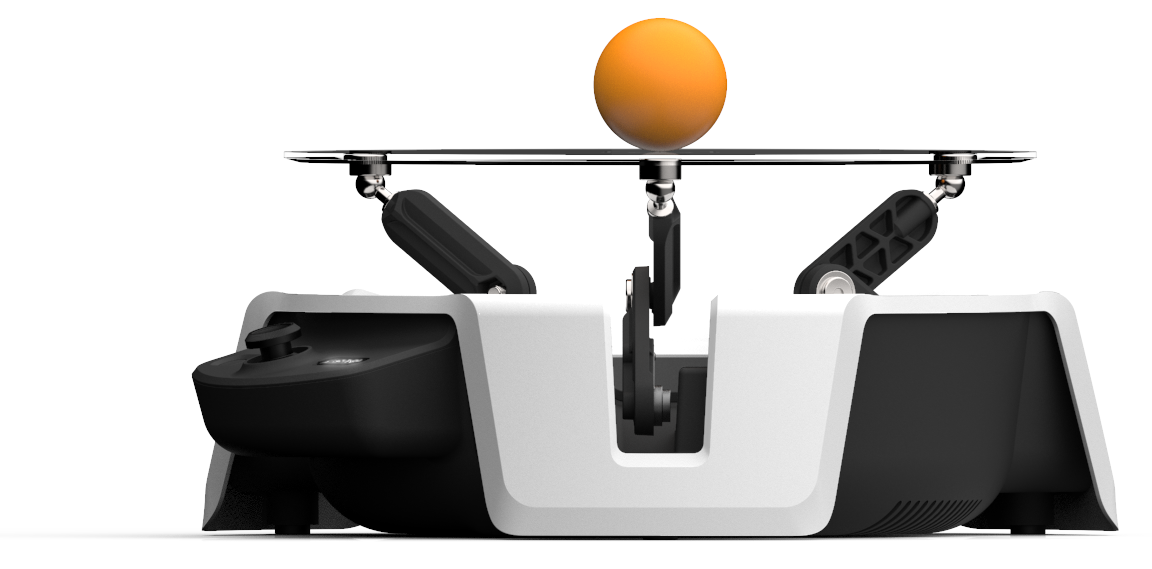

To learn more about Project Moab, including all of the schematics, check out [http://aka.ms/moab.](http://aka.ms/moab.)

## Model Overview

Moab is a dynamic ball-on-plate system is modeled using Simulink and Simscape Multibody. The model contains blocks that represent the multi-body system using imported 3d-CAD parts, joints, contact forces, constraints and sensors. Simscape Multibody formulates and solves the equations of motion for the complete system. During simulation, the system’s states are extracted and sent to a Reinforcement Learning controller (the Bonsai block) which provides the necessary actuation signals to control the plate tilt angles, thus balancing the ball on the plate.

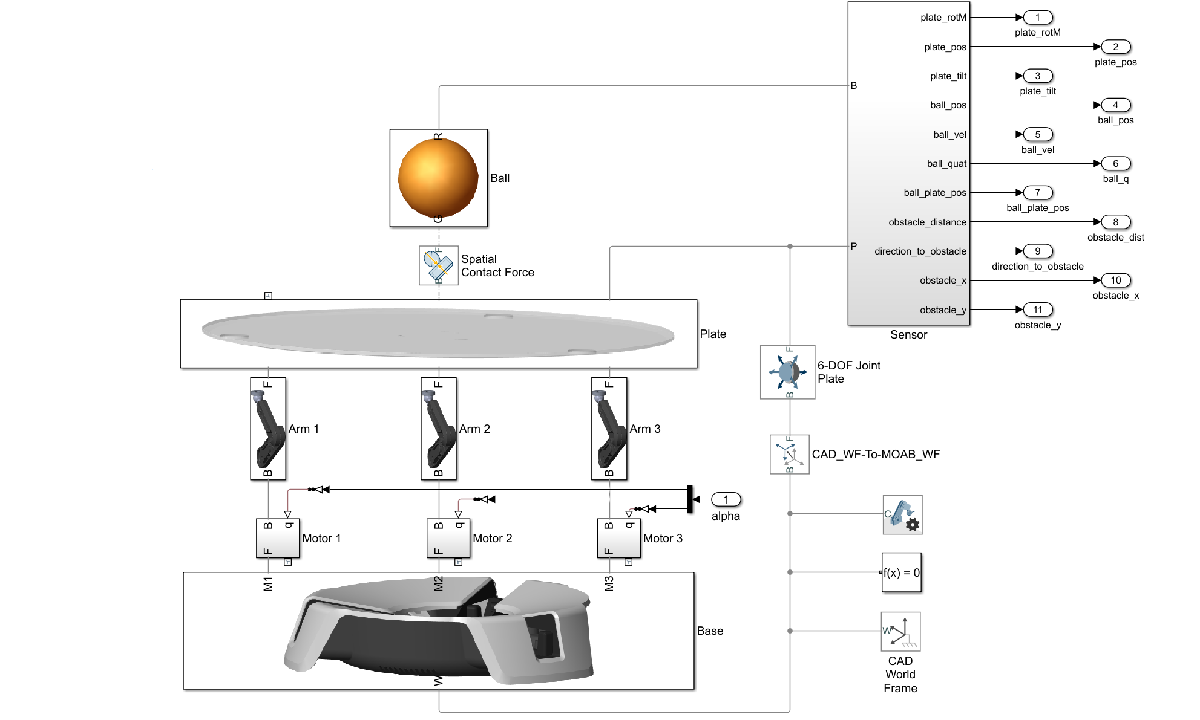

The following products are required to run the model:

- Simulink Version 10.0 (R2019b) or greater

- Simscape [Multibody](https://www.mathworks.com/help/physmod/sm/index.html?s_tid=CRUX_lftnav) (R2019b) or greater

- Bonsai [Toolbox](http://aka.ms/as/bonsai-toolbox) 1.0

- Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup)

### Solver 

To simulate the model, a solver computes the states of the system at successive time steps by applying a numerical method. This numerical method solves a set of ordinary differential equations (ODEs) that represent the ball-on-plate system, in addition to determining the time of the next simulation step and satisfying accuracy requirements. In addition to dynamic behavior, physical systems may have algebraic constraints representing functional relationships between states. To satisfy these constraints along with the ODEs, the model uses a differential algebraic equation (DAE) solver. The choice of solver for this model is [ode23t](https://www.mathworks.com/help/matlab/ref/ode23t.html), which solves moderately stiff ODEs and DAEs with a trapezoidal integration rule.

Other things people might consider: 

- [How Simscape models represent physical systems](https://www.mathworks.com/help/physmod/simscape/ug/how-simscape-models-represent-physical-systems.html)

- [Choose an ODE solver](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html)

- [Making optimal solver choices for physical simulation](https://www.mathworks.com/help/physmod/simscape/ug/making-optimal-solver-choices-for-physical-simulation.html)

- [How Fast Restart improves iterative simulations](https://www.mathworks.com/help/simulink/ug/how-fast-restart-improves-iterative-simulations.html)

### Runtime vs. Compiled Variables

During training, resetting some of the initial states of the model helps the reinforcement learning agent in the Bonsai block learn better. These states are automatically reset by the training algorithm at the start of each episode. To avoid model recompilation due to these changes, the model is simulated in [Fast Restart](https://www.mathworks.com/help/simulink/ug/how-fast-restart-improves-iterative-simulations.html) mode and corresponding Simscape block parameters are set to run-time tunable mode.

To enable view of run-time parameter settings, turn on` MATLAB > Home > Preferences > Simscape > Show run-time parameter settings.`

### **Bonsai Toolbox Sample Time**

The Bonsai block will operate at a discrete sample time of 0.02s. This is the rate at which the block will be executed during simulation and may be different from the model’s sample time which is stepped up and down while the solver computes the states.

## Running the Model

There are two ways to run the model. The first is to test the model with the output states from the Moab subsystem connected to the local sinusoidal block. This enables you to run the model without the connection to Bonsai to get an understanding of how the model works.

## **Run locally using Sinusoid Controller**

To start the model, run the following to setup the correct paths and launch the MOAB.slx file

startup_MOAB;

Make sure the Sinusoid Controller is selected:

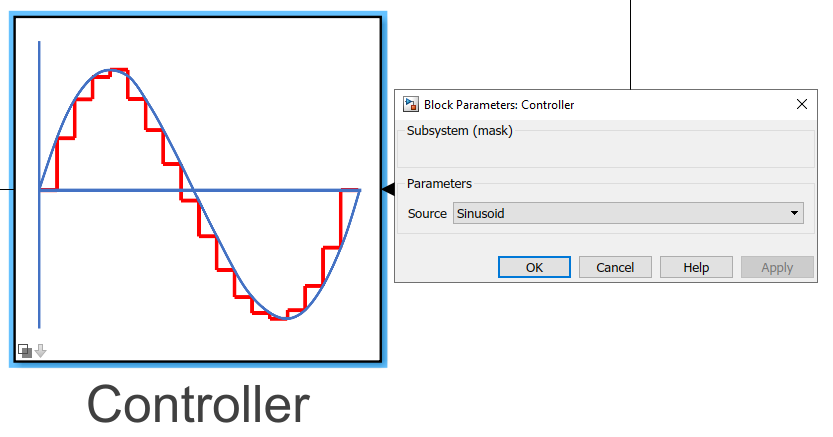

Then click the **Run **button to run the model.

### Multiple Runs

If you would like to test by changing various parameters, including ball size, position and velocity, you can run:

% initialize variables
initializeMoab;

% loop the model in Mechanics Explorer
% will compile the model and run 10 loops
runMoabLocalLoop;

This is a representation of what the Bonsai platform will do once the model is connected to the Bonsai platform. 

### **Modifying Parameters**

In both examples you will see that there are a number of parameters that get modified during a training loop. You may also notice calls to `runMixer`, `calcMOI`, and `cor2SpringDamperParams` functions. These are used to reset the system to the proper initialization steps after the variable values are changed. 

## **Run locally using Bonsai Controller**

After getting acclimated with the Moab model and setting up a Bonsai account, you are now ready to train your first Bonsai brain for Moab. Be sure to select **Bonsai** in the Controller block and save your model. 

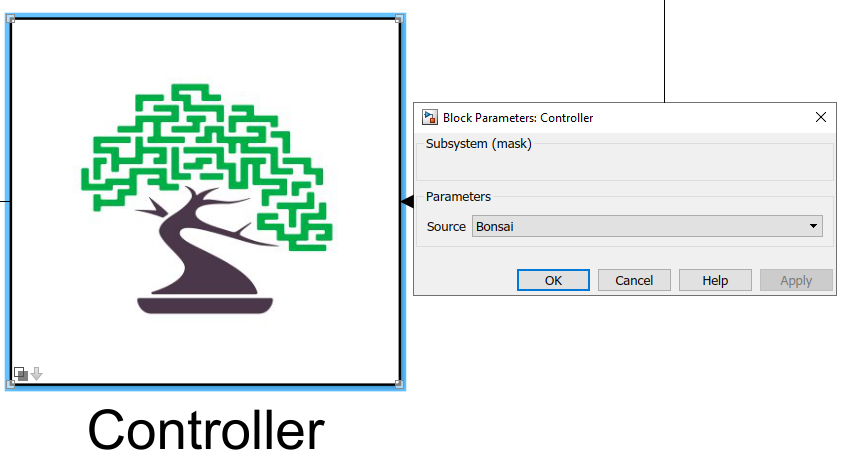

Be sure to **Save** and **Close** the model with the Bonsai Controller selected.

### Connect to Bonsai

If you have not done so, you will need to create a Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup). 

From the Bonsai UI, you will need to capture your Bonsai **Workspace ID **and **Access Key**.

#### Create a Brain

In the Bonsai UI click `+Create Brain:`

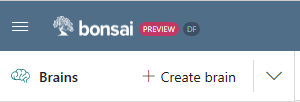

This will prompt for the type of brain to create:

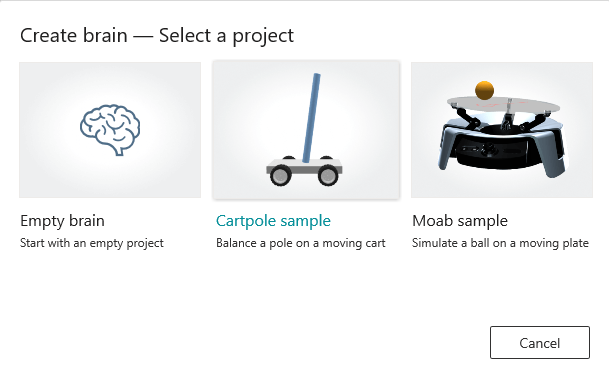

 Select `Moab sample `and enter a name in the subsequent prompt:

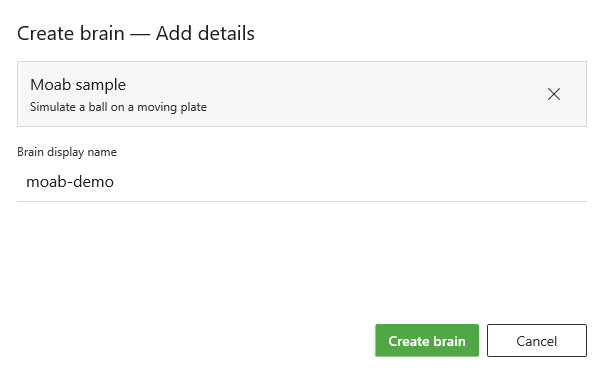

In this example, the brain is called `moab-demo``. `Click the `Create brain` button`.`

This will create your brain and take to to the **Teach** tab:

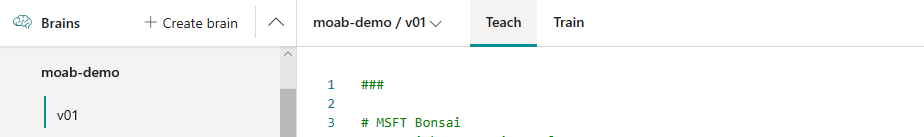

Around line 78, comment out the `package` statement by placing a** # **symbol in front:

to

You are now ready to train locally with the Bonsai Controller.

### The `bonsaiConfig `File

The `bonsaiConfig` script contains the BonsaiConfig function. This is used to setup the connection between your model and the Bonsai platform. Here you describe several key factors:

- **name** - The name of your simulator (you will see this when you connect to Bonsai)

- **url** - Optional. The URL used to connect the Bonsai API service

- **timeout** -- Optional. The value in seconds for a timeout. A default value of 60 seconds is used if this is not explicitly set. **If you receive timeouts when running bonsaiTrain, increase this value up to 300**.

- **workspace** - The workspace value obtained from the Bonsai platform.

- **accessKey** - the access key obtained from the Bonsai platform.

- **outputCSV** - Optional. When running locally, this can be helpful for debugging your model and the Bonsai connection.

- **stateSchema** - *Important. *This is the *order* of the values as they appear in the input parameter of the Bonsai block. Even if you use a Bus as your input the Bonsai block must understand the order of the values. These names must match what is in your inkling code in Bonsai. 

- **actionSchema** - The actions the brain will perform. Input ports to the Moab subsystem. The names must match what is in your inkling code from Bonsai. Order is important. 

- **configSchema** - The values that the Bonsai brain will send during a training episode. These are used as configuration parameters to initialize the model with different states, such as ball size, position, or velocity. 

**Note:** Your model may contain more states than what is in your inkling code for Bonsai. It is OK to have additional states that you send - these are ignored by the platform during execution. However, you must send all states that are required by the inkling code. If you do not, you will receive an error from the platform with an immediate Unregister command

### Edit `bonsaiConfig`

Now open the `bonsaiConfig` file and replace 

`<your workspace here>` with your Workspace ID 

`<your access key here>` with your Access Key (*not *key ID)

% add workspace id
% add access key

edit bonsaiConfig;


You do not need to change any other values other than `workspace` and `accessKey`.

### Run Training with a Single Local Instance 

Now that the connection to Bonsai has been configured, run the `bonsaiTrain` script

bonsaiTrain; 

Once you see the Sim successfully registered message, switch over to the [Bonsai UI](http://preview.bons.ai), click the `Train` button`. `

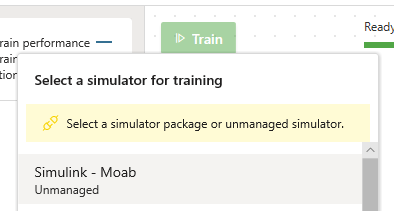

Select `Simulink - Moab` simulator (this assumes you left the .name value the same in bonsaiConfig). 

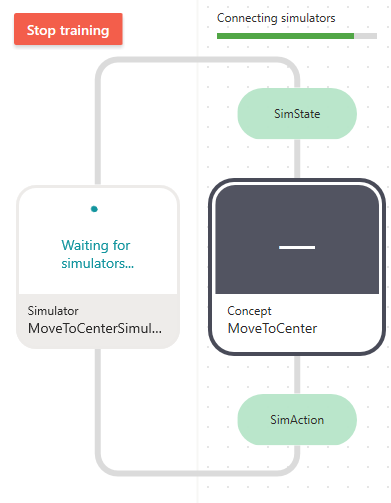

After a short time (typically <2 minutes) the sim will connect:

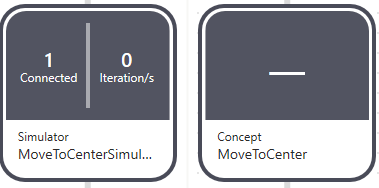

At this point the model is launched and parameters are set, so you may see a delay while this occurs and Mechanics Explorer launches.

After this process completes you will see the iterations per second displayed: 

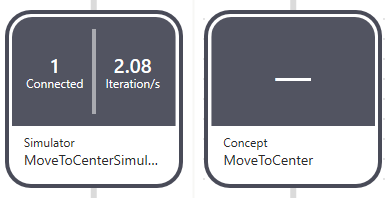

You will see a series of outputs indicating message passing to the Bonsai brain.

Connection speeds vary, but most models operate at about 3 iterations per minute. 

To stop training, click `Stop Training `in the Bonsai UI.

**Note:** You may need to use `Ctrl+C` to break out of the simulator in MATLAB. 

## Zip, Upload and Scale Your Model

Once you have verified your model connects locally, you can close Simulink and zip the entire contents of the folder that contains the model. 

For example, if your folder structure is:

`moab`

`└─── CAD`

`|    └── ... step files ...   `

`└─── Images`

`|    └── ... image files ...      `

`└─── Scripts_Data`

`|    └── calcMOI.m`

`|    └── cor2SpringDamperParams.m   `

`|    └── MOAB_PARAMS.m  `

`|    └── runMixer.m`

`|    └── runMoabLocalLoop.m`

`|─── bonsaiConfig.m`

`|─── bonsaiTrain.m`

`|─── MOAB.slx`

`|─── readme.md`

`└─── startup_MOAB.m`

Then you only need to zip the parent **moab** folder. It is suggested you remove your` slprj` folder and` .slxc `files before zipping up the folder contents. You also do not need the` moab_log.csv `file`. `Call the file `moab.zip. `

**Note: **The uploaded simulator images only support Normal acceleration mode and will error trying to compile the model in Azure.

### Upload the Model

Back in the Bonsai UI, next to `Simulators``,` click the `Add sim` button.

This will open a dialog:

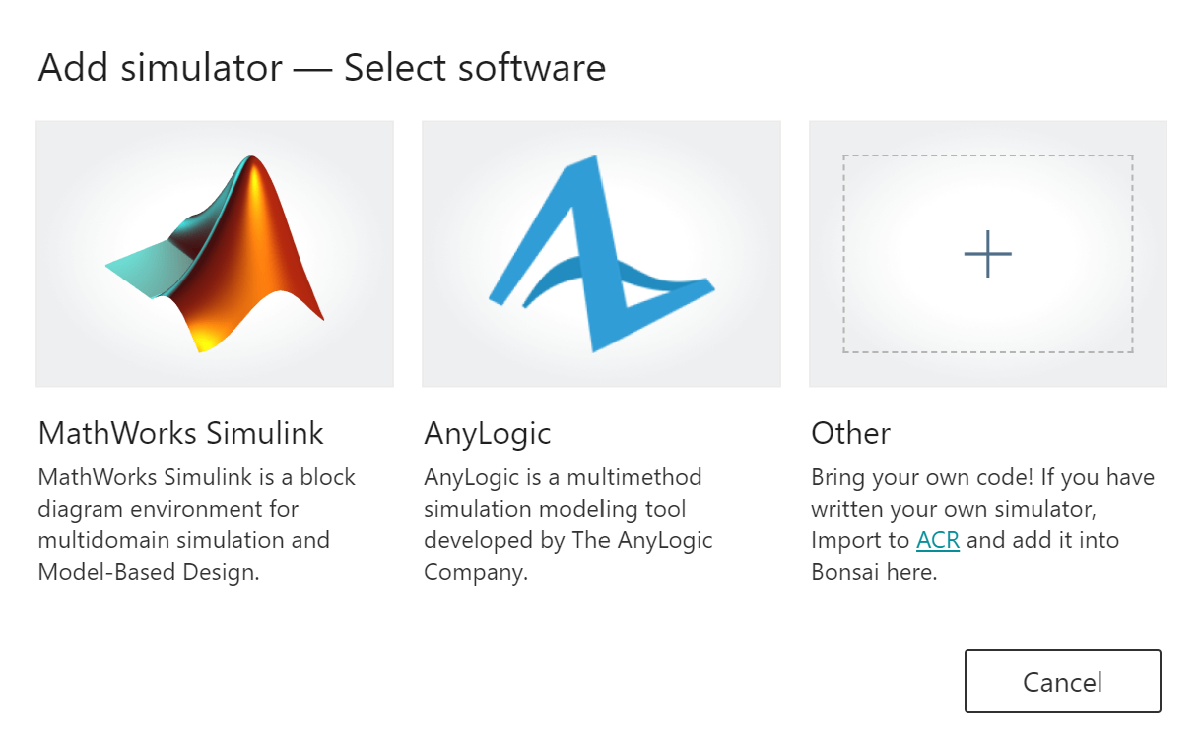

Select `MathWorks``. `Then you can upload your zipp file`:`

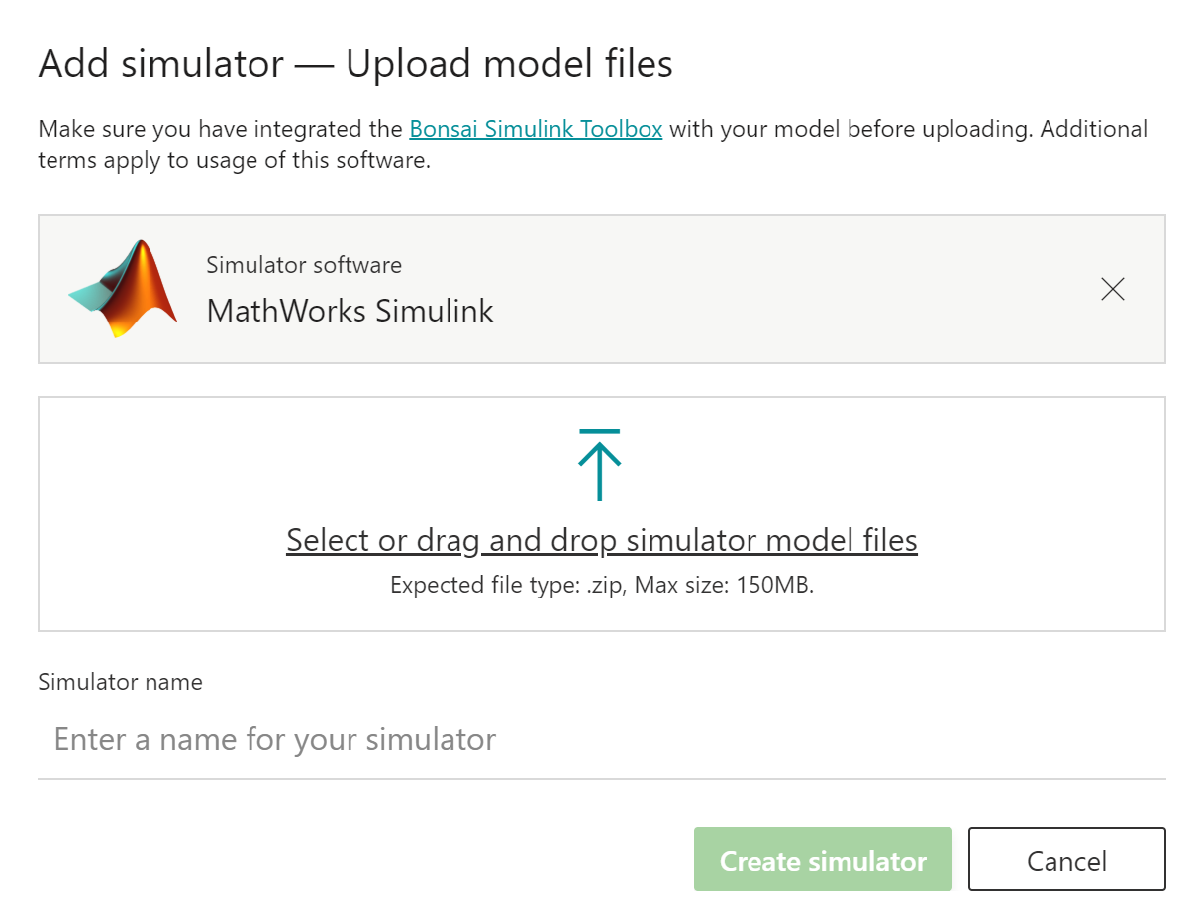

Select or drag the `moab.zip `file created previously`. `

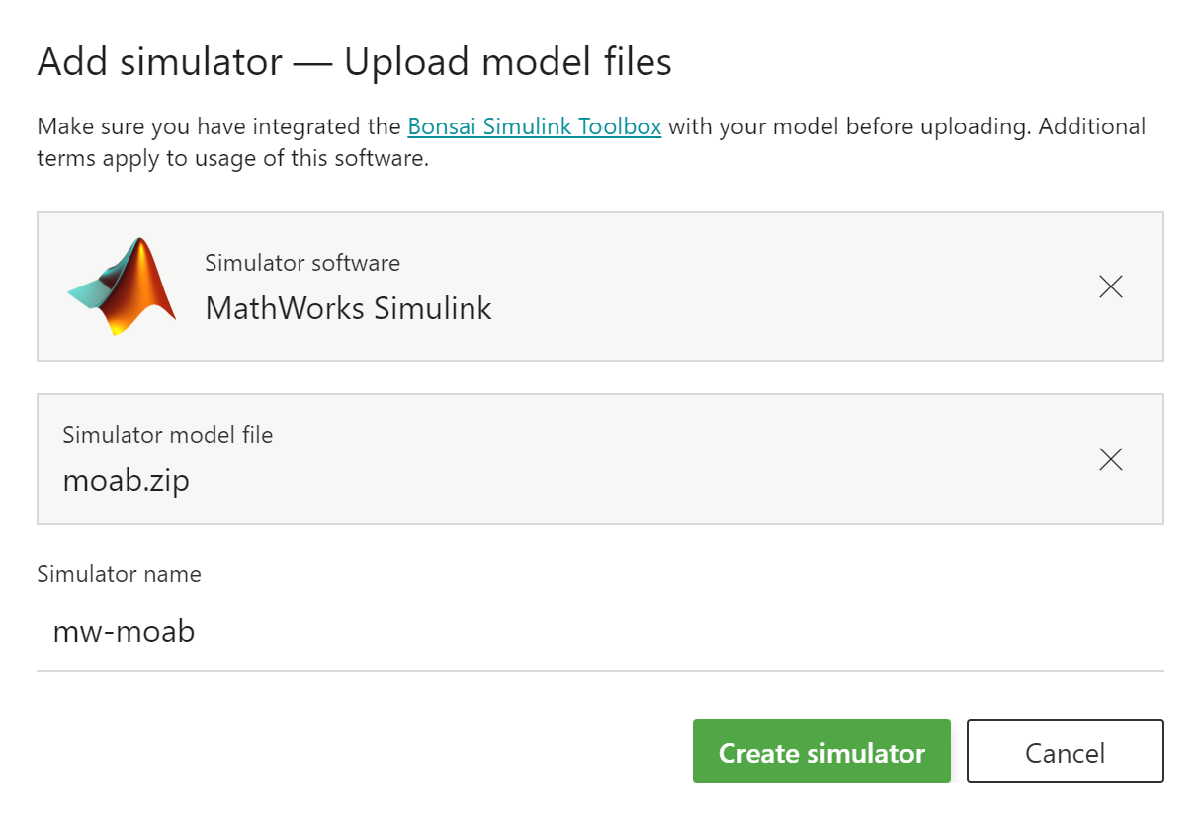

Give your simulator a name, then click `Create simulator``. `

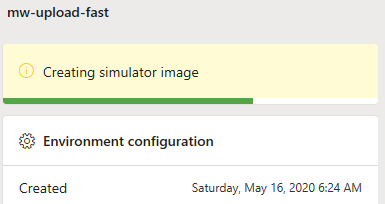

**Note: ***It may take up to 20 minutes to create the simulator image. *You will the ACR path displayed after successful creation:

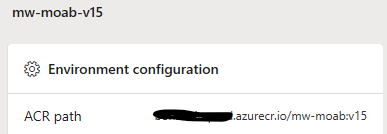

After the simulator is created you will see the new simulator appear under the `Simulators`` section.`

**Note: **Be sure your brain is not training prior to changing the package statement.

Now click the `Teach` tab. 

In the simulator definition, just after the open brackets, add back the package statement using the name of the simulator you gave during the Add Simulator dialog above.

### Scale Your Training

Now click the `Train` button for your brain. This will create several instances (from 1-50) using your uploaded model to train your brain.

**Note: **It may take up to 10 minutes for your simulators to connect.

## Tutorials

There are a number of tutorials outlined on the [Project Moab](http://aka.ms/moab) site, so the step-by-step instructions are not repeated here. You will run the tutorials in the Bonsai UI. When you run the tutorials, remember to change your package name to `<simulator_name_from_upload>` to use your uploaded Simulink model for the tutorials.If you prefer to test each tutorial in Simulink, you will need to have the package statement commented out in inkling and connect your simulator as shown previously using the brain and version specific to the tutorial you are working on.

Below you will see some examples about how the Simulink model performs during the tutorials.

### Tutorial 1

[Tutorial 1](https://aka.ms/moab/tutorial1) is introduces you to the machine teaching paradigm used by Moab and how to integrate with the Moab model. The Moab model has been designed to be used with the same inkling that is in Tutorial 1. However, you will change the package statement to use your uploaded Moab model.

Speed will vary, but after about 318,000 iterations, the brain will achieve its goals:

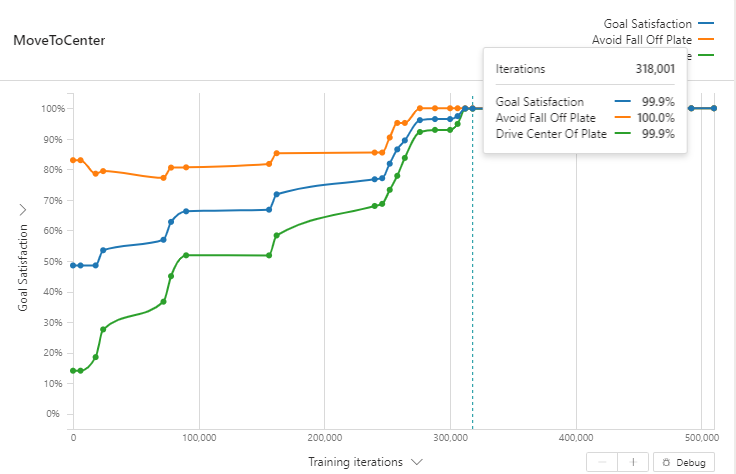

### Tutorial 2

[Tutorial 2](https://aka.ms/moab/tutorial2) introduces domain randomization. Domain randomization is used to train the brain to use allow Moab to balance balls other than a ping pong ball.

Speed will vary, but after about 474,000 iterations, the brain will achieve its goals:

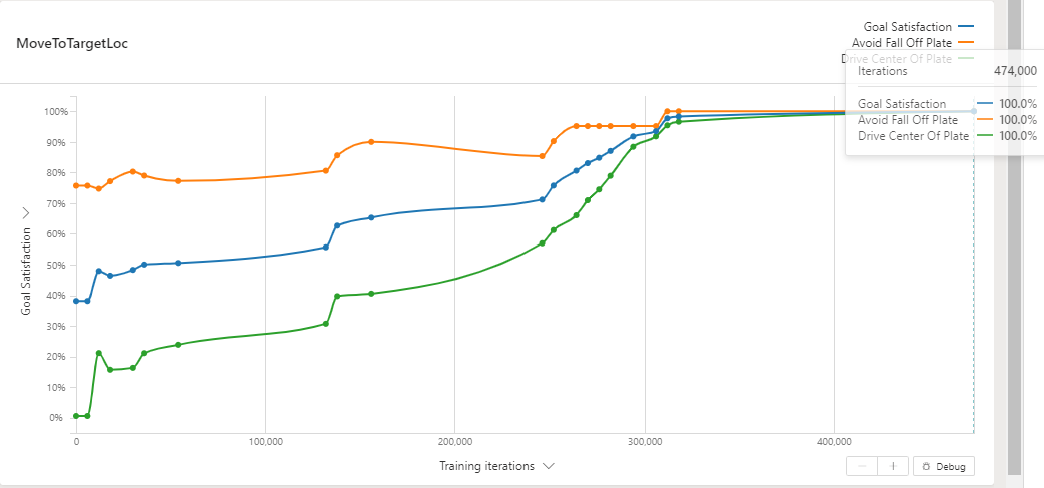

## Assessing Brain Performance

Assessment allows you to test the performance of a trained brain while still hosting that brain in the Bonsai platform. 

After training your brain(s) you will want to assess their performance. Run:

bonsaiAssess;

Make sure your Bonsai Controller is enabled.

Click the `Run` button.

In the Bonsai UI, click the `Start Assessment `button.

Click the `Simulink - Moab` simulator. 

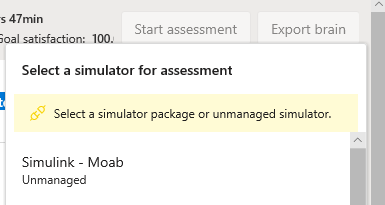

Your local model will iterate using the brain in assessment mode.

If you receive the message `Last event was Unregister, done requesting events `then you may need to increase the timeout value in bonsaiConfig.